This is a demo of how to map the indices generated by RRT navigation to the actual grid and then plot a trajectory.

We start by loading relevant data.

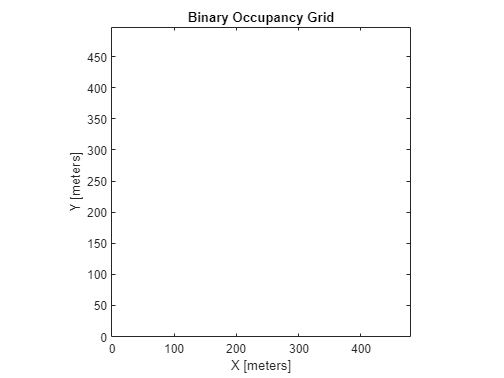

load('idx_matrix_new.mat') % measurement indices associated with each trajectory. The indices vary from 1 to 238560
load('rxCordsstandard.mat') % measurement indices converted into x,y,z co-oridnates
load('mymap.mat') % binary occupancy grid
load('velocities_new.mat') % velocity for respective trajectory

NTrajs = 100; % total number of trajectories
NTimeSamps = 3e3; % total number of time samples. Each spaced 20 ms apart.

% showing the grid
figure()
show(map)

Choosing a random trajectory to plot


traj_chosen = randi([1 NTrajs])

traj_chosen = 15

Extracting the measurement indices of the chosen trajectory

idxes_of_chosen_traj = idxmatrix(traj_chosen,:);
size(idxes_of_chosen_traj)

ans =            1        3000


Velocity for the current trajectory. Units are m/s

velocity_of_the_traj = vvec(traj_chosen)/2e-2

velocity_of_the_traj = 4.5935

Getting x-y co-ordinates from the measurement indices. Note that we only extract x and y co ordinates

true_cords_of_chosen_traj = rxcords(idxes_of_chosen_traj,1:2);

Plotting the trajectory on top of binary occupany grid

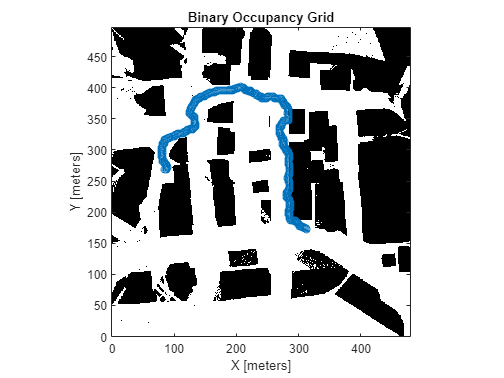

figure()
show(map)
hold on
scatter(true_cords_of_chosen_traj(:,1),true_cords_of_chosen_traj(:,2))